Prob1

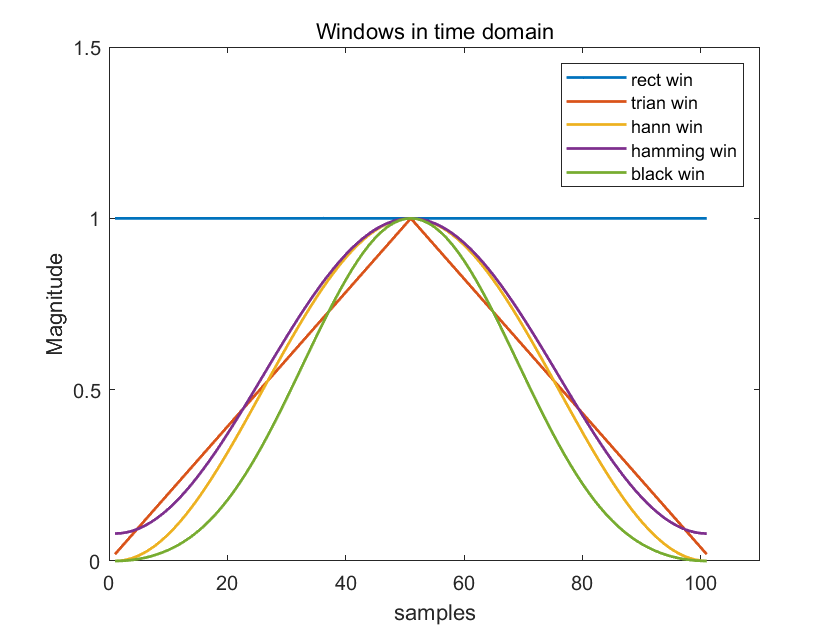

% plot the window
L = 101;
[w1,w2,w3,w4,w5] = window_plot(L);
figure;
plot(w1, 'LineWidth', 1.4), hold on
plot(w2, 'LineWidth', 1.4), hold on
plot(w3, 'LineWidth', 1.4), hold on
plot(w4, 'LineWidth', 1.4), hold on
plot(w5, 'LineWidth', 1.4), hold off
legend('rect win', 'trian win', 'hann win', 'hamming win', 'black win')
xlim([0,110]), ylim([0,1.5]), ylabel('Magnitude'), xlabel('samples')
title('Windows in time domain')

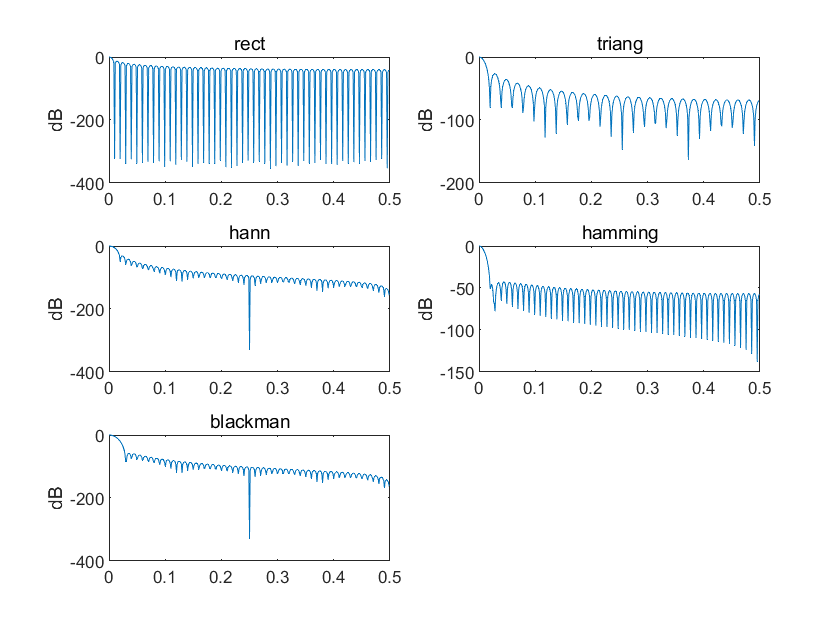


% log form
W1 = fft(w1, L*8);   % zero-padding
W2 = fft(w2, L*8);
W3 = fft(w3, L*8);
W4 = fft(w4, L*8);
W5 = fft(w5, L*8);

% magnitude only
W1_abs = abs(fftshift(W1));
W2_abs = abs(fftshift(W2));
W3_abs = abs(fftshift(W3));
W4_abs = abs(fftshift(W4));
W5_abs = abs(fftshift(W5));

f = (-L*4:L*4-1) ./ (L*8);

W1_db = 20*log10(W1_abs/max(W1_abs));
W2_db = 20*log10(W2_abs/max(W2_abs));
W3_db = 20*log10(W3_abs/max(W3_abs));
W4_db = 20*log10(W4_abs/max(W4_abs));
W5_db = 20*log10(W5_abs/max(W5_abs));

figure;

subplot(321)
plot(f, W1_db), ylabel('dB'), xlim([0, 0.5])
title('rect')
subplot(322)
plot(f, W2_db), ylabel('dB'), xlim([0, 0.5])
title('triang')
subplot(323)
plot(f, W3_db), ylabel('dB'), xlim([0, 0.5])
title('hann')
subplot(324)
plot(f, W4_db), ylabel('dB'), xlim([0, 0.5])
title('hamming')
subplot(325)
plot(f, W5_db)
title('blackman'), ylabel('dB'), xlim([0, 0.5])

function [w1,w2,w3,w4,w5] = window_plot(L)
    if L\2==0
        disp('please enter an odd number')
    else
        w1 = rectwin(L);
        w2 = triang(L);
        w3 = hann(L);
        w4 = hamming(L);
        w5 = blackman(L);
    end
end